# Projekt 7

#### **Przykład 1**

Tworzenie elementów strukturujących.

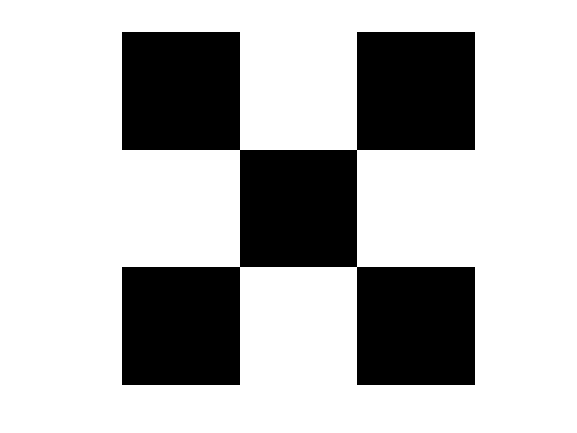

se=strel('arbitrary',[0 1 0;1 0 1;0 1 0]); 
figure; imshow(getnhood(se),'InitialMagnification','fit');

Przydatne funkcje:* imdilate, imerode, imopen, imclose, bwmorph, bwhitmiss*

### Zadanie 1

Na obrazie *bacteria.bmp* przeprowadź operację dylatacji, a następnie porównaj wynik jej działania z obrazem oryginalnym odejmując obrazy we właściwej kolejności. To samo wykonaj dla operacji erozji.

im_1 = imread('data/bacteria.bmp')

im_1 = 300×300 uint8 matrix
    69    52    54   181   254   162    16     9    18    22    24    23    20    19    71    79    87   121   156   183   170   132    99    66    45    38    35    42    41    41    39    25    20    16    17    17    17    17    14    14    19    18    22    18    15   199   252   147    53    58
    77    68    97   191   252   254   120    34    26    19    27    25    15    67   103    92   170   240   249   249   245   248   245   175   103    65    45    39    31    41    27    20    15    16    16    16    15    16    16    13    14    17    23    15    31   248   250   100    46    60
    74    98    92    92   223   254   143    38    36    34    22    16    39   116   119   190   246   252   252   253   254   252   253   247   208   101    52    31    57    39    16    20    17    19    18    19    17    13    15    14    15    18    23    12    46   253   244    74    49    65
    96    90    84    56   157   251   189    24    26    38    44   

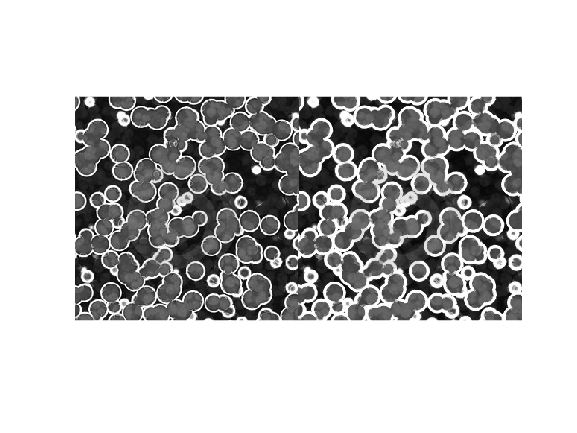


dilatedim_1 = imdilate(im_1,se);
imshowpair(im_1,dilatedim_1,'montage')

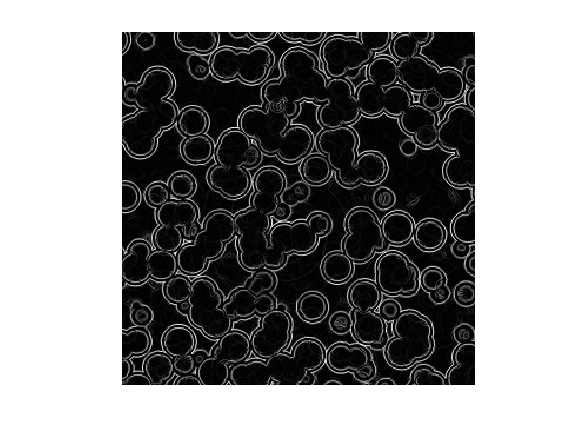


dif = dilatedim_1 - im_1;
figure; imshow(dif)

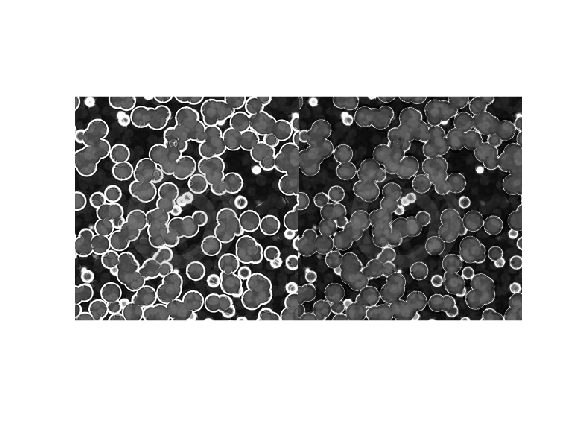


erodedim_1 = imerode(im_1,se);
imshowpair(im_1,erodedim_1,'montage')

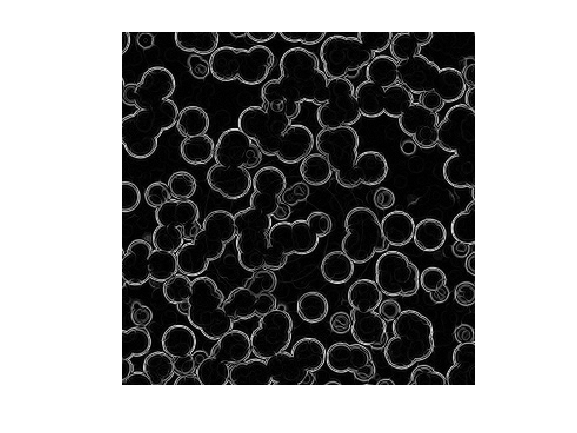

dif = im_1 - erodedim_1;
figure; imshow(dif)

### Zadanie 2

Wczytaj obraz *KPO.gif*, a następnie zbinaryzuj go. Za pomocą odpowiednich operacji morfologicznych usuń odstające elementy i wypełnij luki.

im_2 = imread('data/KPO.gif')

im_2 = 478×784 uint8 matrix
   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251
   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251
   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251   251
   251   251   251   251   251   251   251   251   251   251   251   

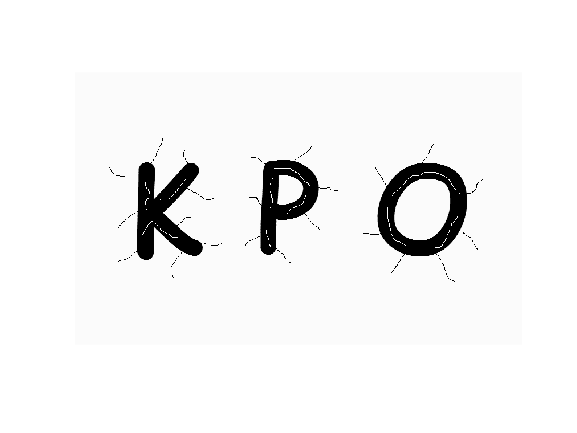

figure; imshow(im_2)

im_2 = imbinarize(im_2,0.5)

im_2 = 478×784 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   

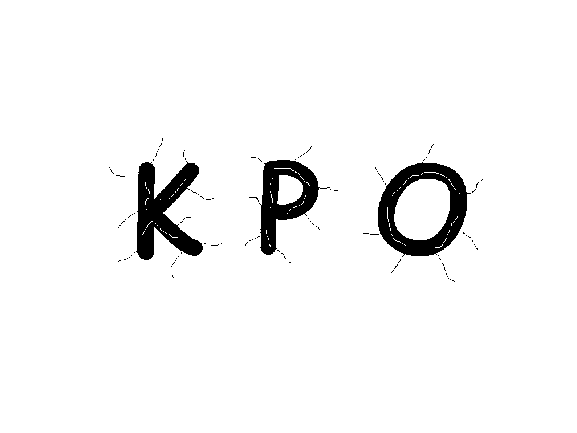

figure;imshow(im_2)

cleaned_im_2 = bwmorph(imopen(imclose(im_2, se), se), 'clean')

cleaned_im_2 = 478×784 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   

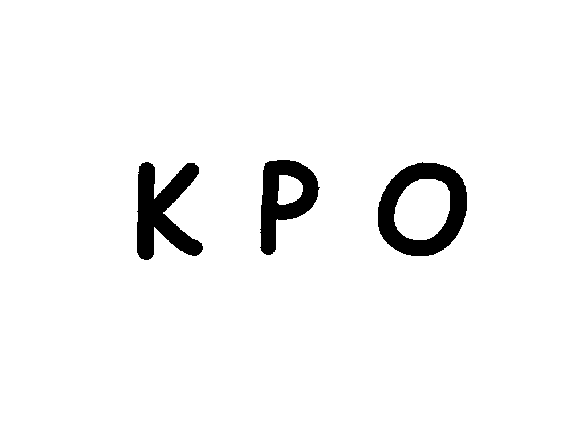



figure; imshow(cleaned_im_2)

### Zadanie 3

Stwórz w dowolnym programie graficznym rysunek białego prostokąta na czarnym tle i zapisz go w bezstratnym formacie. Załaduj obraz do Matlaba, zamień na obraz binarny, a następnie przeprowadź operacje: szkieletyzacji oraz ścieniania morfologicznego.

im_3 = imread('data/pr.png')

im_3 = 461×684×3 uint8 array
im_3(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

im_3=rgb2gray(im_3); 
im_3 = imbinarize(im_3,0.5)

im_3 = 461×684 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

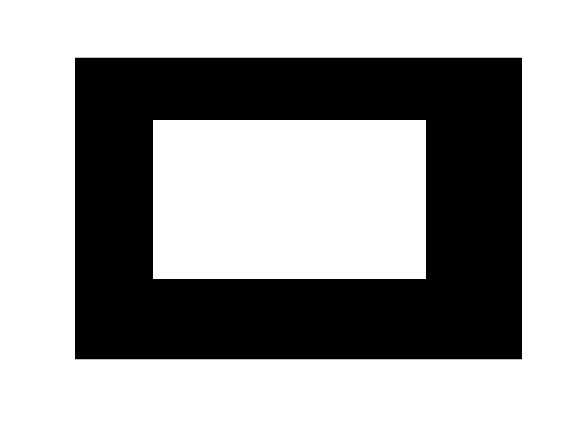

figure; imshow(im_3)


skel_im_3 = bwmorph(im_3, 'skel', Inf)

skel_im_3 = 461×684 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

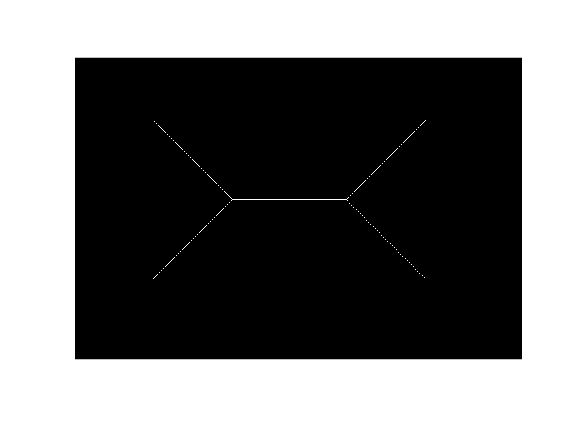

figure; imshow(skel_im_3)

thin_im_3 = bwmorph(im_3, 'thin', Inf)

thin_im_3 = 461×684 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

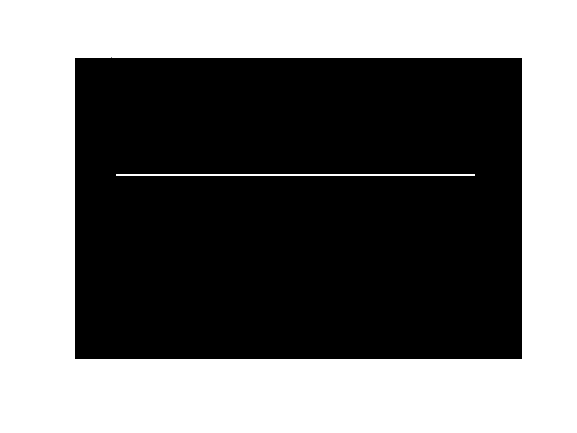

figure; imshow(thin_im_3)

% trzeba powiększyć, żeby było coś widać

### Zadanie 4

Na uprzednio zbinaryzowanym obrazie *naczynia1.jpg *przeprowadź szkieletyzację, a następnie za pomocą odpowiednich operacji morfologicznych usuń "gałązki" oraz piksele izolowane.

im_4 = imread('data/naczynia1.jpg')

im_4 = 300×225 uint8 matrix
     1     1     1     1     1     1     1     1    10     0     6     2     3     3     6     3    10     0    12    17    28    95   197   216   213   232   233   219   242   239   226   216   224   220   204   205   207   222   213   203   212   221   220   209   204   205   209   216   217   225
     0     0     0     0     0     0     0     0     0     7     7     0     4     6     5     2     1    23    22    75   163   201   214   243   231   235   226   216   226   225   203   208   226   215   200   206   210   220   211   206   209   221   218   205   203   210   215   217   219   230
     0     0     0     0     0     0     0     0     7     6     0     1     1     0     0     9     9    35   142   207   201   216   208   224   223   216   213   219   224   225   193   210   216   202   192   206   216   222   213   210   213   223   217   202   203   213   216   214   223   234
     0     0     0     0     0     0     0     0     0     1     3   

im_4 = imbinarize(im_4,0.5)

im_4 = 300×225 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   

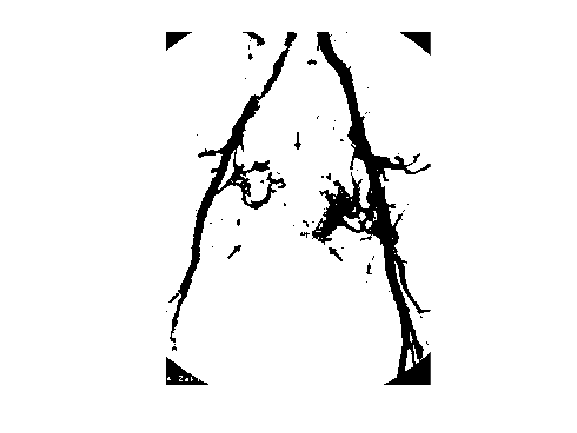

figure; imshow(im_4)

skel_im_4 = bwmorph(im_4, 'skel', Inf)

skel_im_4 = 300×225 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

br = bwmorph(skel_im_4, 'branchpoints');
brs = find(br);

en = bwmorph(skel_im_4, 'endpoints');
[y,x] = find(en);


to_rem = zeros(300,225);

for i = 1:numel(y)
    
    D = bwdistgeodesic(skel_im_4,x(i),y(i));
    dis = min(D(brs));
    
    if dis < 20
        to_rem(D < dis) = 1;
    end

end


cleaned_skel_im_4 = bwmorph((skel_im_4 - to_rem), 'clean')

cleaned_skel_im_4 = 300×225 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

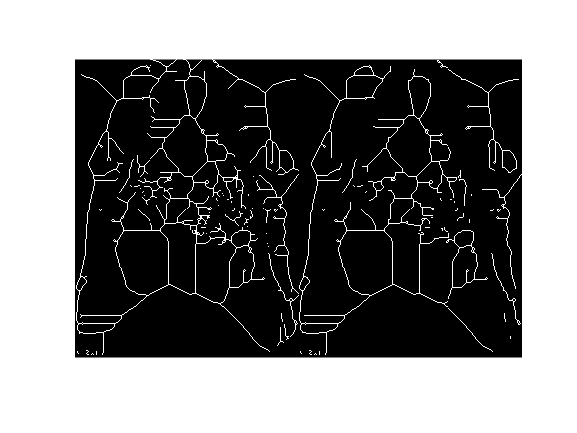


imshowpair(skel_im_4,cleaned_skel_im_4,'montage')

### Zadanie 5

W pliku *statki.mat *zapisane są położenia statków 4-masztowych, 3-masztowych, 2-masztowych i 1-masztowych. 

Wczytaj plik *statki.mat *za pomocą instrukcji:

statki = load('data/statki.mat');
L1 = statki.L1;

a następnie na obrazie L1 za pomocą odpowiedniej funkcji Matlaba zatop te statki, które spełniają zasady gry, czyli nie stykają się ani brzegami, ani rogami, nie zaginają się, za to mogą się obracać o 90 stopni. Obowiązuje założenie, że do zatopienia dowolnego statku wystarczy jedno trafienie. Wyświetl na osobnych obrazach miejsca trafień w każdy rodzaj statku i podpisz rysunek zgodnie z tym rodzajem. Policz ile statków z każdego rodzaju zostało zatopionych i wyświetl tę informację (w konsoli lub oknie).

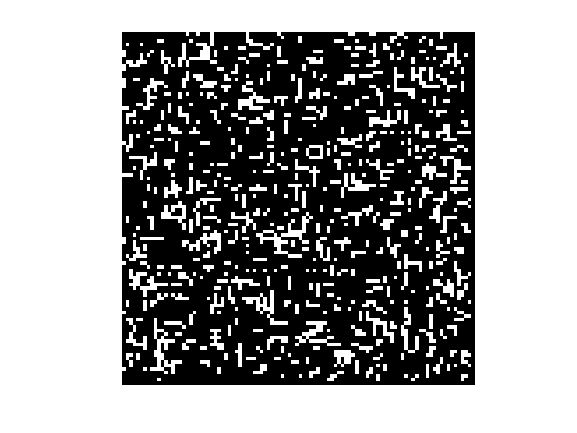

figure; imshow(L1)

int_1 = [-1 -1 -1; -1 1 -1; -1 -1 -1]

int_1 =     -1    -1    -1
    -1     1    -1
    -1    -1    -1


int_2_1 = [-1 -1 -1 -1; -1 1 1 -1; -1 -1 -1 -1]

int_2_1 =     -1    -1    -1    -1
    -1     1     1    -1
    -1    -1    -1    -1


int_2_2 = [-1 -1 -1; -1 1 -1; -1 1 -1; -1 -1 -1]

int_2_2 =     -1    -1    -1
    -1     1    -1
    -1     1    -1
    -1    -1    -1



int_3_1 = [-1 -1 -1 -1 -1; -1 1 1 1 -1; -1 -1 -1 -1 -1]

int_3_1 =     -1    -1    -1    -1    -1
    -1     1     1     1    -1
    -1    -1    -1    -1    -1


int_3_2 = [-1 -1 -1; -1 1 -1; -1 1 -1; -1 1 -1; -1 -1 -1]

int_3_2 =     -1    -1    -1
    -1     1    -1
    -1     1    -1
    -1     1    -1
    -1    -1    -1



int_4_1 =[-1 -1 -1 -1 -1 -1; -1 1 1 1 1 -1; -1 -1 -1 -1 -1 -1]

int_4_1 =     -1    -1    -1    -1    -1    -1
    -1     1     1     1     1    -1
    -1    -1    -1    -1    -1    -1


int_4_2 = [-1 -1 -1; -1 1 -1; -1 1 -1; -1 1 -1; -1 1 -1; -1 -1 -1]

int_4_2 =     -1    -1    -1
    -1     1    -1
    -1     1    -1
    -1     1    -1
    -1     1    -1
    -1    -1    -1



m1 = bwhitmiss(L1,int_1)

m1 = 100×100 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0 


m2_1 = bwhitmiss(L1,int_2_1)

m2_1 = 100×100 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   

m2_2 = bwhitmiss(L1,int_2_2)

m2_2 = 100×100 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

m2 = m2_1 + m2_2

m2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  


m3_1 = bwhitmiss(L1,int_3_1)

m3_1 = 100×100 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

m3_2 = bwhitmiss(L1,int_3_2)

m3_2 = 100×100 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

m3 = m3_1 + m3_2

m3 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  


m4_1 = bwhitmiss(L1,int_4_1)

m4_1 = 100×100 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

m4_2 = bwhitmiss(L1,int_4_2)

m4_2 = 100×100 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

m4 = m4_1 + m4_2

m4 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

sum_1 = sum(sum(m1)')

sum_1 = 110

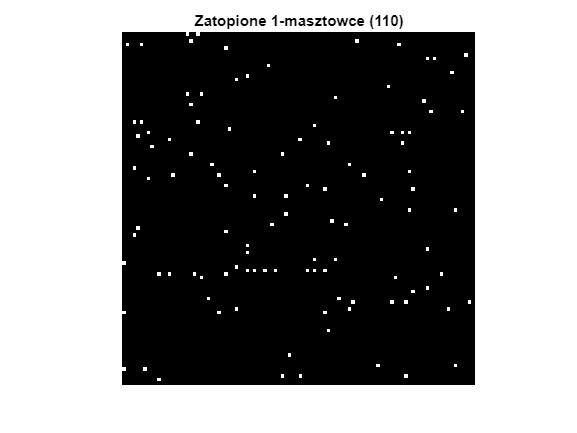

figure; imshow(m1)
title ("Zatopione 1-masztowce (" + sum_1 + ")")


sum_2 = sum(sum(m2)')

sum_2 = 108

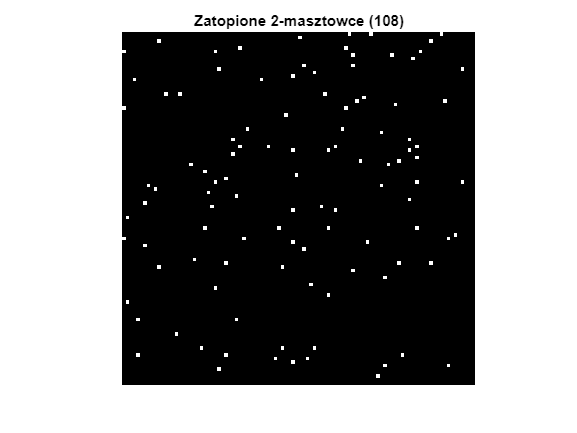

figure; imshow(m2)
title ("Zatopione 2-masztowce (" + sum_2 + ")")

sum_3 = sum(sum(m3)')

sum_3 = 41

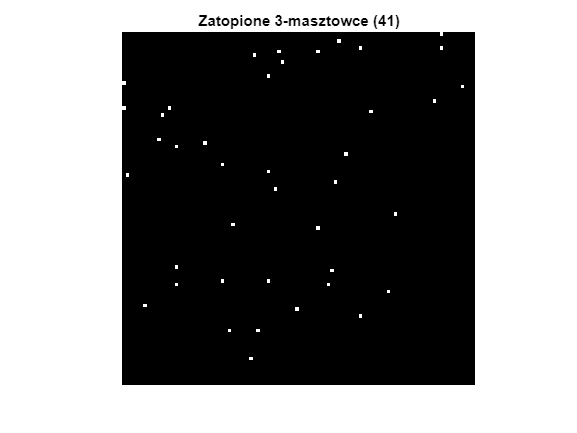

figure; imshow(m3)
title ("Zatopione 3-masztowce (" + sum_3 + ")")

sum_4 = sum(sum(m4)')

sum_4 = 15

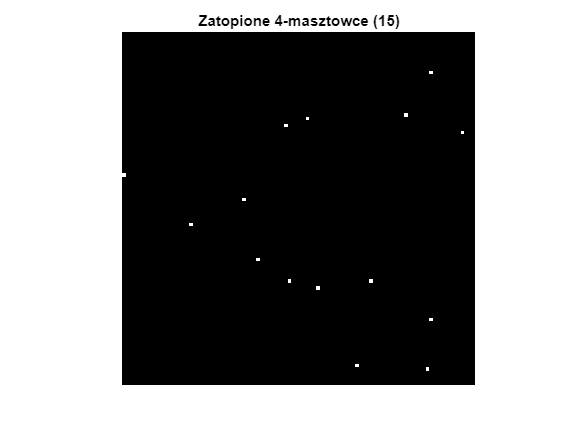

figure; imshow(m4)
title ("Zatopione 4-masztowce (" + sum_4 + ")")